guessTheForm('form 1 foot.csv',3500,7200) % 3500, 7200

ans = 2.2254

guessTheForm('form 1 foot.csv', 8200, 12200) % 8200, 12200

ans = 2.1391


guessTheForm('form 2 foot.csv',1800,5800) % 1800, 5800

ans = 1.9293

guessTheForm('form 2 foot.csv', 8000, 9000) % 7000, 11000

ans = 1.6226

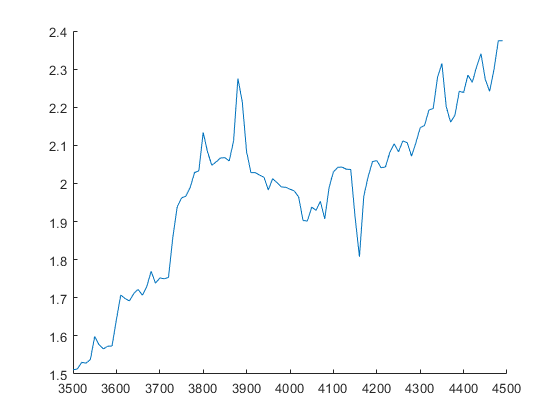

clf
hold on
numPoints = 100;
starts = zeros(1, numPoints);
ratios = zeros(1, numPoints);
startIndex = 3500;
stepSize = 10;
for i=1:numPoints
    start = startIndex - stepSize + stepSize * i;
    ratio = guessTheForm('form 1 foot.csv',start,start + 2000); % 3500, 7200
    ratios(i) = ratio;
    starts(i) = start;
end
plot(starts, ratios)
hold off

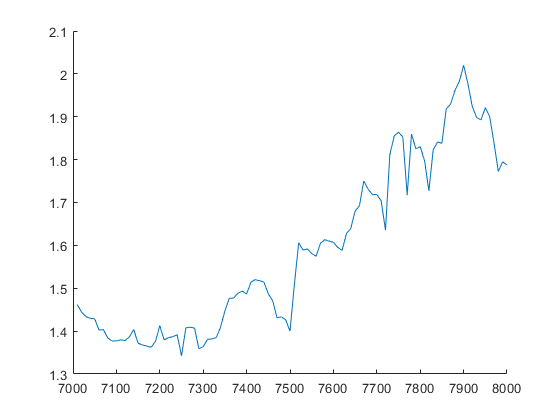


clf
hold on
numPoints = 100;
starts = zeros(1, numPoints);
ratios = zeros(1, numPoints);
for i=1:numPoints
    start = 7000 + 10 * i;
    ratio = guessTheForm('form 2 foot.csv',start,start + 2500); % 3500, 7200
    ratios(i) = ratio;
    starts(i) = start;
end
plot(starts, ratios)
hold off

function guessedForm = guessTheForm(inputData, startIndex, endIndex)
    
    foot = csvread(inputData, 1,0);
    footX = foot(:,3)';
        
    
    if startIndex == 0
       startIndex = 1; 
    end
    if endIndex == 0
        endIndex = max(size(foot));
    end
    footXOne = footX(startIndex:endIndex);
    
    nFootOne = endIndex - startIndex + 1;
    Fs = 100;
    f = linspace(-Fs/2, Fs/2 - Fs/nFootOne, nFootOne) + Fs/(2*nFootOne)*mod(nFootOne, 2);
    FOOTXONE = fft(footXOne);
    
    spectrum = fftshift(abs(FOOTXONE));
    filter_val = 2;
    filter_inds = -1 * filter_val <=abs(f) & abs(f) >= filter_val; 
    spectrum_filt = spectrum;
    spectrum_filt(filter_inds) = spectrum_filt(filter_inds)/10;
    largestPower = max(spectrum_filt);
    secondLargestPower = max(spectrum_filt(spectrum_filt<max(spectrum_filt)));
    ratio = largestPower / secondLargestPower;
    guessedForm = ratio;
    
    
end